%iDopaNeuroCT
d=10:50:700;
model_FVA=iDopaNeuroC;
modelname1='iDopaNeuroC';
for k = 1:length(d)
     demand = d(1,k);
     model_FVA = changeRxnBounds(model_FVA, 'ATPM', demand, 'b');
            genericMetaboContribution;
            demandATP1.atpm(k,1) = d(1,k);
            demandATP1.rxns{k,1} = metaboContribution.metabo.reactions;%all ATP production rxns
            demandATP1.total{k,1} = sum([metaboContribution.metabo.reactions{:,2}]);%all atp production flux
            demandATP1.highest{k,1} = metaboContribution.metabo.maxContRxn{1,1};%highest contribution rxn
            demandATP1.PGK(k,1) = metaboPGK; %PGK flux proportion
            demandATP1.PYK(k,1) = metaboPYK;
            demandATP1.ATPS4mi(k,1) = metaboATPS4mi;
            demandATP1.r0408(k,1) = metabor0408;
            demandATP1.SUCOASm(k,1) = metaboSUCOASm;
            demandATP1.NDPK6(k,1) = metaboNDPK6;
            demandATP1.RE0124C(k,1) = metaboRE0124C;
            demandATP1.NDPK2(k,1) = metaboNDPK2;
            demandATP1.NMNATr(k,1) = metaboNMNATr;
            demandATP1.glycolysis{k,1} = cell2mat(metaboPGK) + cell2mat(metaboPYK); %PGK+PYK proportion
end
% iDopaNeuroC
model_FVA=iDopaNeuroCT;
modelname2='iDopaNeuroCT';
for k = 1:length(d)
     demand = d(1,k);
     model_FVA = changeRxnBounds(model_FVA, 'ATPM', demand, 'b');
            genericMetaboContribution;
            demandATP2.atpm(k,1) = d(1,k);
            demandATP2.rxns{k,1} = metaboContribution.metabo.reactions;%all ATP production rxns
            demandATP2.total{k,1} = sum([metaboContribution.metabo.reactions{:,2}]);%all atp production flux
            demandATP2.highest{k,1} = metaboContribution.metabo.maxContRxn{1,1};%highest contribution rxn
            demandATP2.PGK(k,1) = metaboPGK; %PGK flux proportion
            demandATP2.PYK(k,1) = metaboPYK;
            demandATP2.ATPS4mi(k,1) = metaboATPS4mi;
            demandATP2.r0408(k,1) = metabor0408;
            demandATP2.SUCOASm(k,1) = metaboSUCOASm;
            demandATP2.NDPK6(k,1) = metaboNDPK6;
            demandATP2.RE0124C(k,1) = metaboRE0124C;
            demandATP2.NDPK2(k,1) = metaboNDPK2;
            demandATP2.NMNATr(k,1) = metaboNMNATr;
            demandATP2.glycolysis{k,1} = cell2mat(metaboPGK) + cell2mat(metaboPYK); %PGK+PYK proportion
end

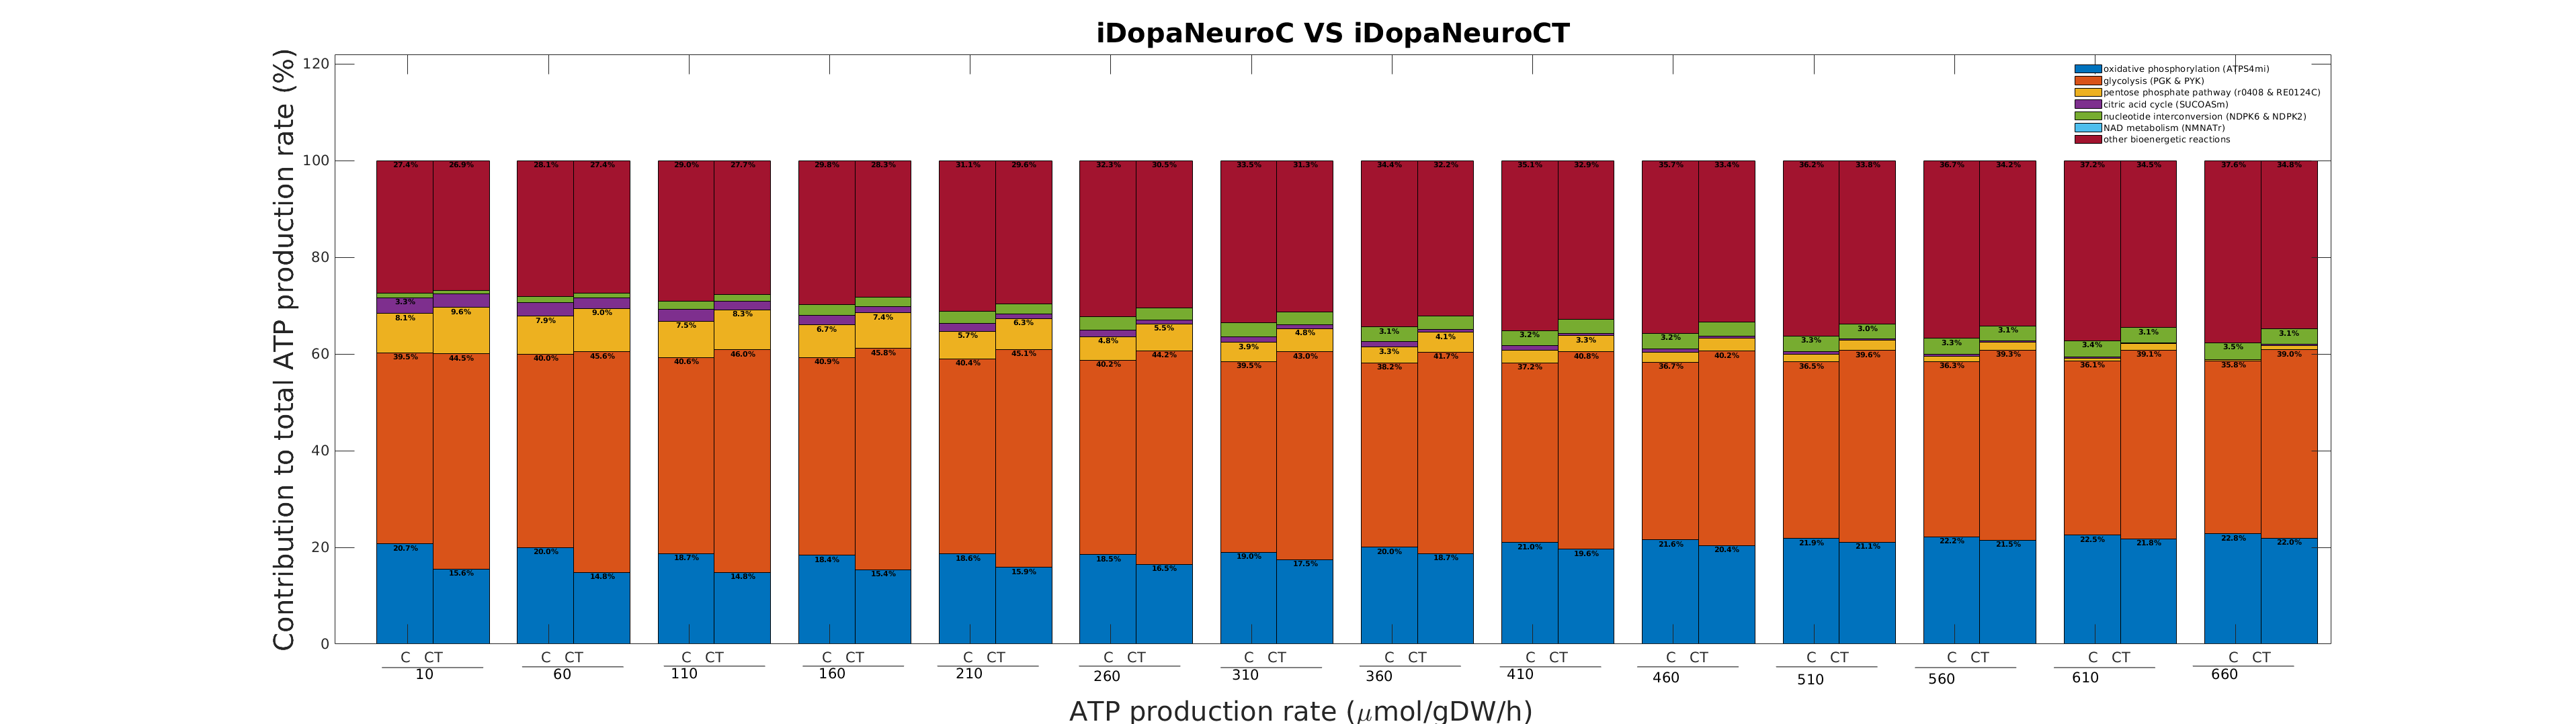

%plot stack bar chart
model1=demandATP1;
model2=demandATP2;
w1 = 0.4;
str = {'%'};
f2= figure('units','normalized','outerposition',[0 0 1 1]);
colormap(lines)
ydata = [cell2mat(model1.ATPS4mi), ...
    cell2mat(model1.glycolysis),(cell2mat(model1.r0408) ...
    + cell2mat(model1.RE0124C)), cell2mat(model1.SUCOASm),...
    (cell2mat(model1.NDPK6) + cell2mat(model1.NDPK2)),...
    cell2mat(model1.NMNATr)];
for j = 1:size(ydata,1);
    odata(j,1) = 100 - sum(ydata(j,:));
end
ydata(:,7) = odata;
bar(d+5, ydata, w1, 'stacked');
for m=1:size(ydata,1);
    xpos = d(m)+5;
    for n=1:size(ydata,2);
        if ydata(m,n)>3; %so that the labels don't overlap with other labels
            labels_stacked=num2str(ydata(m,n),'%.1f');
            label = strcat(labels_stacked, '%');
            hText = text(xpos, sum(ydata(m,1:n),2), label);
            set(hText, 'VerticalAlignment','top', 'HorizontalAlignment',...
                'center','FontSize',8, 'Color','k','FontWeight', 'Bold');
        end
    end
end
hold on
ydataPD = [cell2mat(model2.ATPS4mi), ...
    cell2mat(model2.glycolysis),(cell2mat(model2.r0408) ...
    + cell2mat(model2.RE0124C)), cell2mat(model2.SUCOASm),...
    (cell2mat(model2.NDPK6) + cell2mat(model2.NDPK2)),...
    cell2mat(model2.NMNATr)];
for m = 1:size(ydataPD,1);
    odataPD(m,1) = 100 - sum(ydataPD(m,:));
end
ydataPD(:,7) = odataPD;
bar(d+25, ydataPD, w1, 'stacked');
for m=1:size(ydataPD,1);
    xpos = d(m)+25;
    for n=1:size(ydataPD,2);
        if ydataPD(m,n)>3; %so that the labels don't overlap with other labels
            labels_stacked=num2str(ydataPD(m,n),'%.1f');
            label = strcat(labels_stacked, '%');
            hText = text(xpos, sum(ydataPD(m,1:n),2), label);
            set(hText, 'VerticalAlignment','top', 'HorizontalAlignment',...
                'center','FontSize',8, 'Color','k', 'FontWeight', 'Bold');
        end
    end
end
set(gca,'FontSize',16, 'XTick',...
    [16 66 116 166 216 266 316 366 416 466 516 566 616 666], ...
    'XTickLabel', {...
    '      C   CT','      C   CT','      C   CT','      C   CT',...
    '      C   CT','      C   CT','      C   CT','      C   CT',...
    '      C   CT','      C   CT','      C   CT','      C   CT',...
    '      C   CT','      C   CT'});

legend({'oxidative phosphorylation (ATPS4mi)', 'glycolysis (PGK & PYK)', ...
    'pentose phosphate pathway (r0408 & RE0124C)', ...
    'citric acid cycle (SUCOASm)',...
    'nucleotide interconversion (NDPK6 & NDPK2)', 'NAD metabolism (NMNATr)',...
    'other bioenergetic reactions'}, 'FontSize',10, 'box', 'off');
title([modelname1 ' VS ' modelname2],'FontSize',30);
xlabel({'ATP production rate (\mumol/gDW/h)'},'FontSize',30, ...
    'Position', [334 -10.5 0])
ylabel({'Contribution to total ATP production rate (%)'},'FontSize',30);
xlim([-10,700]);
ylim([0,122]);
set(gca,'XTickLabelRotation',0);
%set(gca,'XTick',[])
figure1 = f2;
annotate
caxis([0 7])